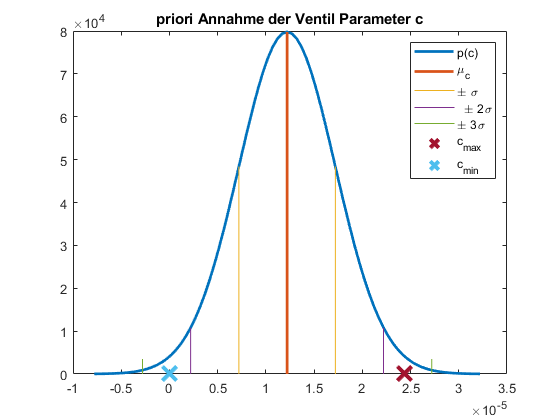

c = 2.44e-5;%2.441e-5
mean = c /2;
sigma = 5e-6;

x = [mean-4*sigma:sigma/10:mean+4*sigma];
y = normpdf(x,mean,sigma);
plot(x,y,"color","#0072BD",'LineWidth',2)
hold on;
plot([mean,mean],[0,y(41)],"color","#D95319",'LineWidth',2);

plot([mean-sigma,mean-sigma],[0,y(31)],"color","#EDB120");
plot([mean+sigma,mean+sigma],[0,y(31)],"color","#EDB120");

plot([mean-2*sigma,mean-2*sigma],[0,y(21)],"color","#7E2F8E");
plot([mean+2*sigma,mean+2*sigma],[0,y(21)],"color","#7E2F8E");

plot([mean-3*sigma,mean-3*sigma],[0,y(16)],"color","#77AC30");
plot([mean+3*sigma,mean+3*sigma],[0,y(16)],"color","#77AC30");

plot(c,0,'x','MarkerSize',15,"color","#A2142F",'LineWidth',3)
plot(0,0,'x','MarkerSize',15,"color","#4DBEEE",'LineWidth',3)
legend("p(c)","\mu_c", "\pm \sigma","", "  \pm 2\sigma","", "\pm 3\sigma","", "c_{max}", "c_{min}");
title("priori Annahme der Ventil Parameter c")